# HW 5 - Bisection and False Position - 9.27

## Problem 1 - Root, bisection method

Use bisection method to determine the drag coefficient needed so that a 95-kg bungee jumper has a velocity of 46 m/s after 9 s of free fall. Start with initial guesses of *x**l* = 0.2 and *x**u* = 0.5 and iterate until the approximate relative error falls below 5%.

Note: The acceleration of gravity is 9.81 m/s2. (Round the final answer to four decimal places.)

The required drag coefficient is *c**d* =  kg/m.

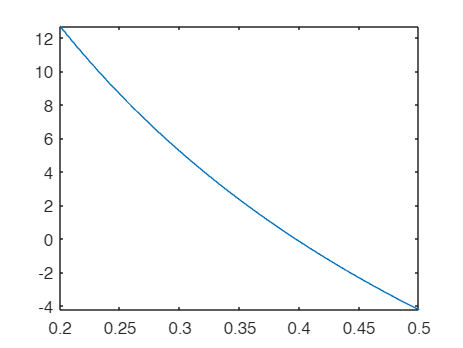

% Not gonna work bc don't have cd. Also need ftn handle.
%   addpath('C:\Users\caleb\..B - School\_A - MATLAB Scripts\_ME 140 Matlab\Ch3 - Programming with MATLAB');
%   v=freefall(t,m,cd);
addpath 'C:\Users\caleb\..B - School\_A - MATLAB Scripts\_ME 140 Matlab\Ch5 - Roots - Bracketing Methods'

% Better solution
t = 9; g = 9.81;
m = 95; xl = 0.2; xu = 0.5;
v = @(cd) sqrt(g*m/cd)*tanh(sqrt(g*cd/m)*t)-46; % that -46 is crucial

fplot(v, [0.2 0.5]);

func = v; es = 5;
[root_v,relErr_v,iter_v] = bisect(func,xl,xu,es)

root_v = 0.3966

relErr_v = 7.2132e-05

iter_v = 20

## Problem 3 - False Position

Use false-position method to determine the drag coefficient needed so that a 95-kg bungee jumper has a velocity of 46 m/s after 9 s of free fall. Start with initial guesses of *x**l* = 0.2 and *x**u* = 0.5 and iterate until the approximate relative error falls below 5%.

Note: The acceleration of gravity is 9.81 m/s2. (Round the final answer to four decimal places.)

The required drag coefficient is *c**d* =  kg/m.

[root,froot,ea,iter]=falsepos(func,xl,xu,es)

root = 0.3987

froot = -0.0988

ea = 1.4046

iter = 3

## Problem 5 - Bisection

According to Archimedes’ principle, the buoyancy force is equal to the weight of fluid displaced by the submerged portion of the object. For the sphere depicted in the figure below, use bisection to determine the height, *h*, of the portion that is above water. Use *r* = 1 m, *ρ**s* = density of sphere = 250 kg/m3, and *ρ**w* = density of water = 1000 kg/m3. (Round the final answer to four decimal places.)

Note that the volume of the above-water portion of the sphere can be computed with the formula

V=πh23(3r−h)

% Derive symbolically
syms r z h
rho = sqrt(r^2 - z^2);
dV = pi*(rho^2);            % integrand as a symbolic expression
V  = int(dV, z, r - h, r);  % integrate w.r.t. z from z=r-h to z=r
simplify(V)

$$ans = -\frac{\pi \,h^{2}\,\left(h-3\,r\right)}{3}$$

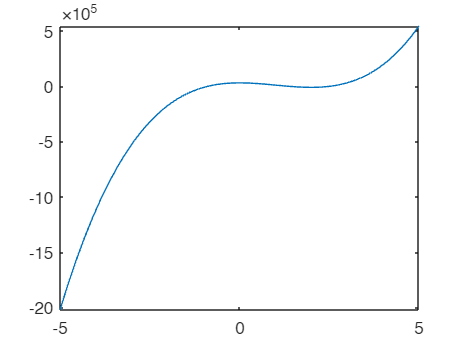


% Derive numerically
r = 1;           % example numeric values
h = 0.3;
dV = @(z) pi*(r^2 - z.^2);  % note elementwise power
V  = integral(dV, r - h, r);

% Actual problem solution
r = 1; % m 
g = 9.81; 
rho_sph = 250; % kg/m^3
rho_w = 1000; % kg/m^3

V_above = @(h) pi*h^2*(r-h/3);
V_sphere = 4/3*pi*r^3;
m_sph = rho_sph*V_sphere; % kg
V_below = @(h) V_sphere - V_above(h);

F_buoy = @(h) rho_w*V_below(h)*g;
F_grav = m_sph*9.81;

% Solve for h
F_net = @(h) F_buoy(h) - F_grav;
fplot(F_net)

[h_neut,relErr_h,iter_v_h] = bisect(F_net,0,2)

h_neut = 1.3473

relErr_h = 7.0784e-05

iter_v_h = 21


% Check solution
(V_above(h_neut)-V_sphere)/V_sphere

ans = -0.2500

rho_w*V_below(h_neut)*g-rho_sph*V_sphere*g

ans = -0.0097